# Son 2: Enregistrement de voix humaine

Tel que pour le son 1, un bruit blanc gaussien sera ajouté à un enregistrement de voix humaine. Les informations pertinentes à savoir pour cet exercise sont : 

        1) Le bruit blanc est réparti également sur l'ensemble des toutes le fréquences du spectre.

        2) La voix humaine se situe majoritairement entre 20 Hz et 600 Hz mais peut aller j'usqu'à 8 KHZ.

        3) L'oreille humaine peut entendre jusqu'à 22 kHz

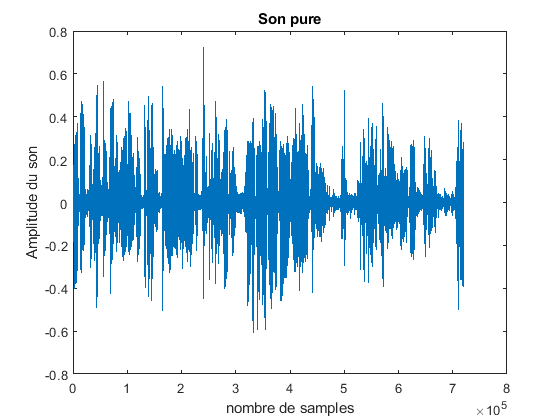

%% Exemple avec un signal de voix et musique 


clear all;
close all;
clc;
format short eng


used_time = 15; % temps en secondes

delay_time = 40 ;% temps en delais en [s] laisser écouler x secs avant échantillionnage
frequencyLimits = [0 24000]; % [Hz]   Seuil de l'audition humaine approx

%% Extraction du signal

% [son_2_sans_perturbation,sampleRate] = %audioread('raspoutine.mp4'); Used to
% exctract sampleRate from original file

% sampleRate est statique a 48000 et sera donc declare de facon staique
sampleRate = 48000;
%time_total = (length(son_2_sans_perturbation)/ sampleRate); % temps en secondes

delay_points = delay_time*sampleRate; % Number of samples to skip 

cropped_sound = audioread('raspoutine.mp4',[(1+delay_points) (sampleRate*used_time+delay_points)]);


sample_point=1:1:length(cropped_sound);

%% Plots PURE sans perturbation
figure
plot(sample_point,cropped_sound(:,1));
title('Son pure')
xlabel('nombre de samples')
ylabel('Amplitude du son')

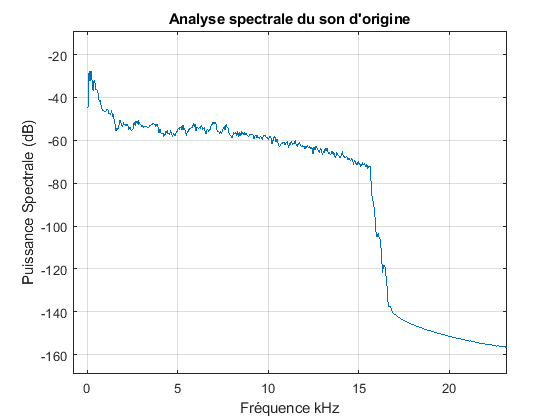



figure
SpectralAnalyser(cropped_sound(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale du son d''origine')

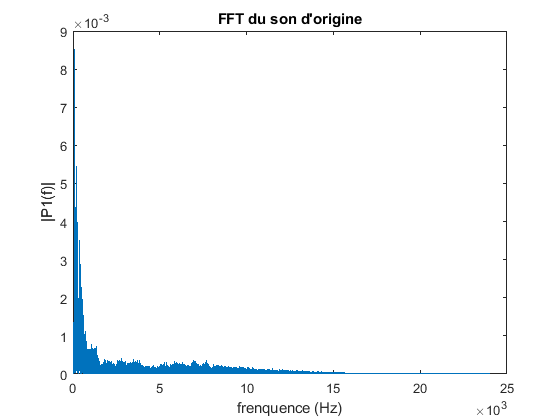


figure
fftPlotter(cropped_sound(:,1),sampleRate);
title('FFT du son d''origine')


%audiowrite('Block\cropped_sound.wav',cropped_sound,sampleRate);
%sound(cropped_sound,sampleRate); % ecouter son sans perturbations

## Son avec perturbation

L'écoute du son permet d'entendre une voix humain ainsi  qu'une petite musique d'ambiance.  La musique sera traité somme du bruit et seulement la voix sera isolé.

Dans  cette section, les fréquences à isoler ainsi que l'origine des perturbations sont connues. Il est donc relativement facile de savoir quelles fréquences isoler et lesquelles couper. Cependant, il peut arriver que le son à isoler ainsi que l'origine du bruit soit inconnue. Les approches suivantes vont supposer que le bruit ainsi que les fréquences à isoler sont inconnue. Afin d'avoir une meilleur idée du son à isoler, nous proposons donc d'appliquer d'abords un filtre passe-bas. Ce premier filtre devrait permettre d'isoler les hautes fréquences et ainsi, permettre d'avoir une meilleur idée des fréquences voulu et des frequences parasites.

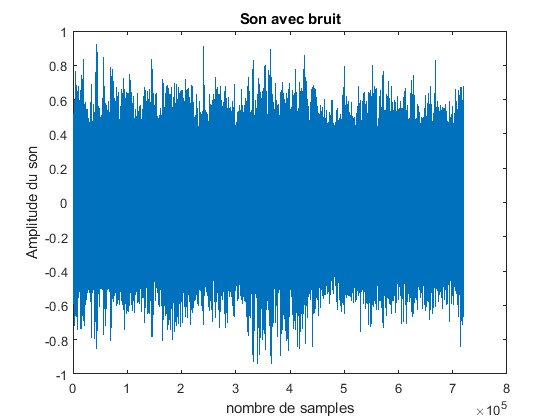

%% ajout du bruit gaussien
SNR = 0; % signal-to-noise ratio


% Le son sera perturbé deux fois afin d'augmenter la quantité de bruit 
son_2_avec_perturbation = awgn(cropped_sound, SNR,  'measured');
son_2_avec_perturbation = awgn(son_2_avec_perturbation, SNR,  'measured');




figure
    plot(sample_point,son_2_avec_perturbation(:,1));
    title('Son avec bruit')
    xlabel('nombre de samples')
    ylabel('Amplitude du son')

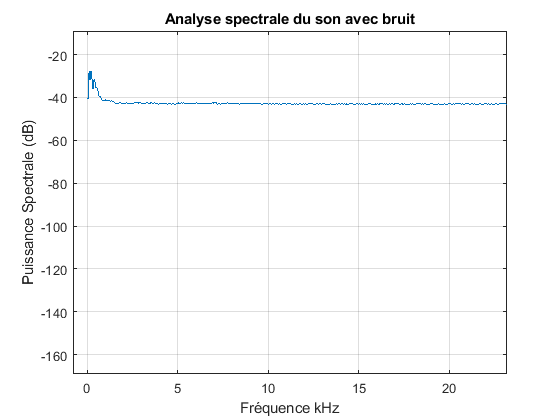


figure
    SpectralAnalyser(son_2_avec_perturbation(:,1),sampleRate,frequencyLimits,0,[0 15]);
    title('Analyse spectrale du son avec bruit')

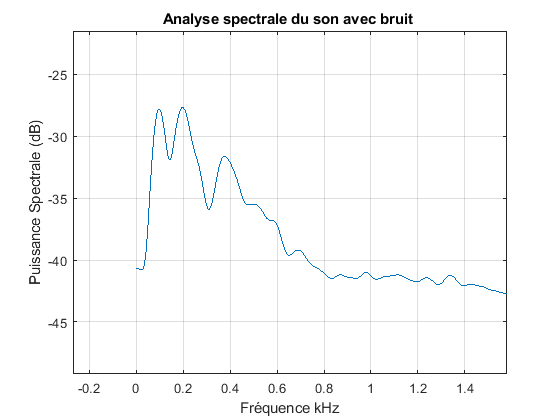



figure
    SpectralAnalyser(son_2_avec_perturbation(:,1),sampleRate,frequencyLimits,0,[0 15]);
    title('Analyse spectrale du son avec bruit ')

    xlim([-0.27 1.58])
    ylim([-49.2 -21.5])

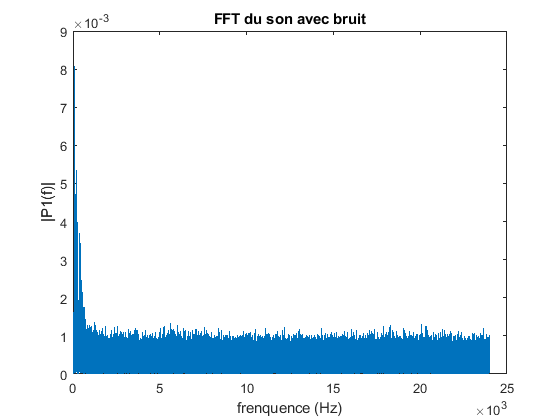

    
figure
    fftPlotter(son_2_avec_perturbation(:,1),sampleRate)
    title('FFT du son avec bruit')


%sound(son_2_avec_perturbation,sampleRate);
%audiowrite('Block\son_2_avec_perturbation.wav',son_2_avec_perturbation,sampleRate);

En regardant la fft du son avec bruit il est possible de voir des peaks jusqu'à environ 800 Hz avant que les son s'entremêle avec les perturbations.

Cependant, en regardant l'analyse spectrale, on peut  voir que le signal possède une puissance jusqu'a envoron 1400 Hz où le signal se stabilise à une puissance de -40 dB.

 À l'écoute, l'application du filtre lowpass est démontre une amélioration de la qualtié du signal par rapport au signal bruité nous savons d'onc que le signal se situe bel et bien dans la section de basses fréquences du spectre fréquenciel.

Sachant que le signal à isoler est composé de voix humaine. Il est possible d'avoir une idée de sa composition fréquenciel.

La voix humaine varie habituellement entre 40 Hz et 600 Hz et entre 20 Hz et 8000 Hz pour le fréquences plus riches.

En appliquant des filtres avec ces fréquences perspective. Il été remarqué que les fréquences le plus interssantes sont [400, 600, 800, 1250 ]  Hz pour cet exemple spécifique.

## Application d'un passe-bas

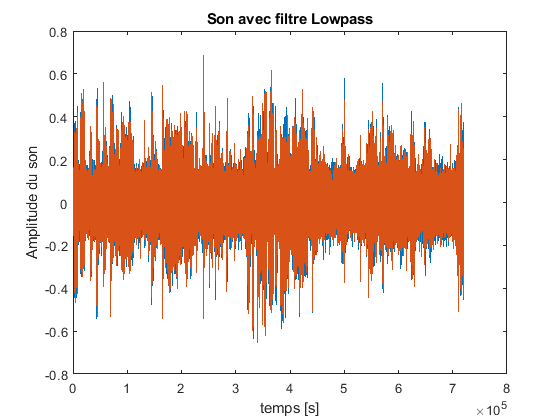


freq_coupure_lowpasse = 1250; % fréquence trouvé par essais erreur. Ce qui corrobore les conclusions de l'analyse spectrale

son_2_filtre_lowpass = lowpass(son_2_avec_perturbation,freq_coupure_lowpasse,sampleRate);

figure
plot(sample_point,son_2_filtre_lowpass)
title('Son avec filtre Lowpass')
xlabel('temps [s]')
ylabel('Amplitude du son')

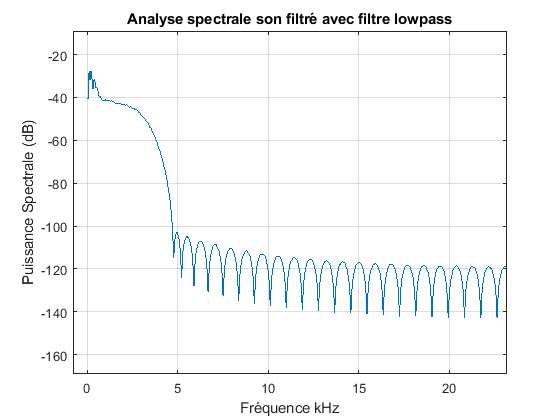


figure
SpectralAnalyser(son_2_filtre_lowpass(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale son filtré avec filtre lowpass');

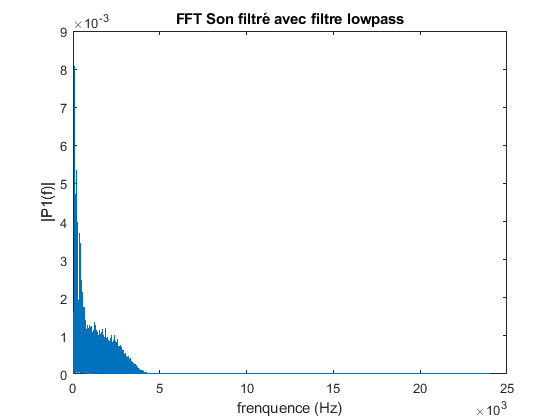


figure
fftPlotter(son_2_filtre_lowpass,sampleRate)
title('FFT Son filtré avec filtre lowpass');


%sound(son_2_filtre_lowpass,sampleRate);
%audiowrite('Block\son_2_filtre_lowpass.wav',son_2_filtre_lowpass,sampleRate);

 À l'écoute, l'application du filtre lowpass est démontre une amélioration de la qualtié du signal par rapport au signal bruité nous savons d'onqu que le signal se situe bel et bien dans la section de basses fréquences du spectre fréquenciel.

Sachant que le signal à isoler est composé de voix humaine. Il est possible d'avoir une idée de sa composition fréquenciel.

La voix humaine varie habituellement entre 20 Hz et 8000 Hz avec des fréquences dominates entres 40 Hz et 600 Hz.

Essayons un filtre passebande avec ces fréquences. 

## passe-bande

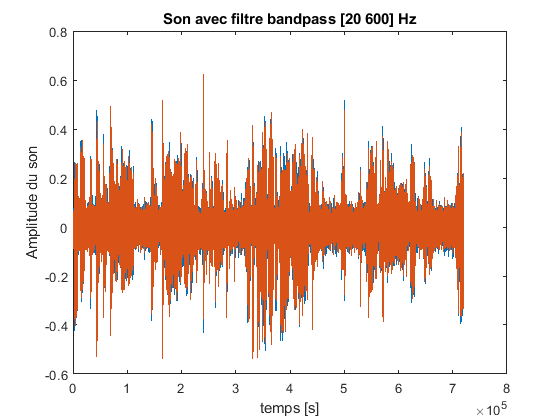


son_2_filtre_bandpass2 = bandpass(son_2_avec_perturbation,[40 900],sampleRate);


%% plot filtre bandpass [20 600] Hz

figure
plot(sample_point,son_2_filtre_bandpass2)
title('Son avec filtre bandpass [20 600] Hz')
xlabel('temps [s]')
ylabel('Amplitude du son')

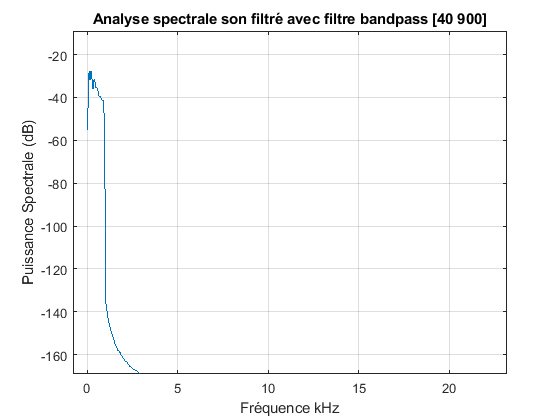


figure
SpectralAnalyser(son_2_filtre_bandpass2(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale son filtré avec filtre bandpass [40 900]');

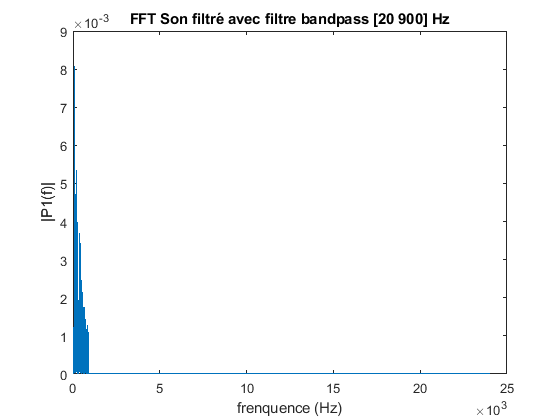


figure
fftPlotter(son_2_filtre_bandpass2,sampleRate)
title('FFT Son filtré avec filtre bandpass [20 900] Hz');

%hold on
%figure


%sound(son_2_filtre_bandpass2,sampleRate);
%audiowrite('Block\son_2_filtre_bandpass2.wav',son_2_filtre_bandpass2,sampleRate);


Appliqu'ons un gain pour compenser les atténuations.

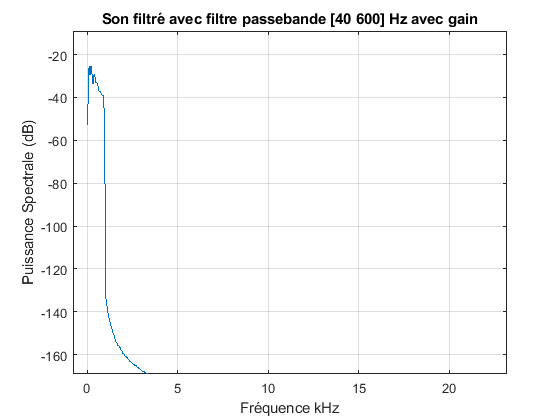

son_2_filtre_bandpass2_2 = son_2_filtre_bandpass2*1.3; % application d'un gain

figure
SpectralAnalyser(son_2_filtre_bandpass2_2,sampleRate,frequencyLimits,0,[0 15]);
title('Son filtré avec filtre passebande [40 600] Hz avec gain')

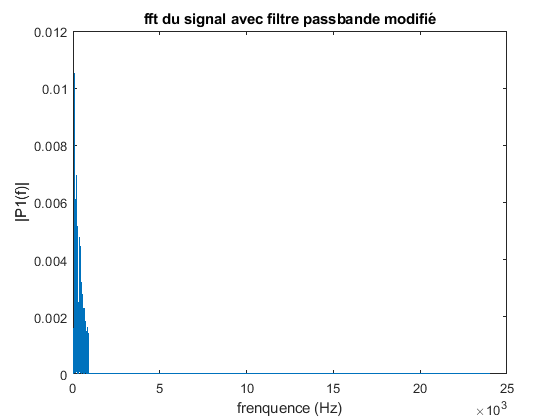


figure 
fftPlotter(son_2_filtre_bandpass2_2,sampleRate);
title('fft du signal avec filtre passbande modifié')


%sound(son_2_filtre_bandpass2_2,sampleRate);
%audiowrite('Block\son_2_filtre_bandpass2_2.wav',son_2_filtre_bandpass2_2,sampleRate);


## Comb filter

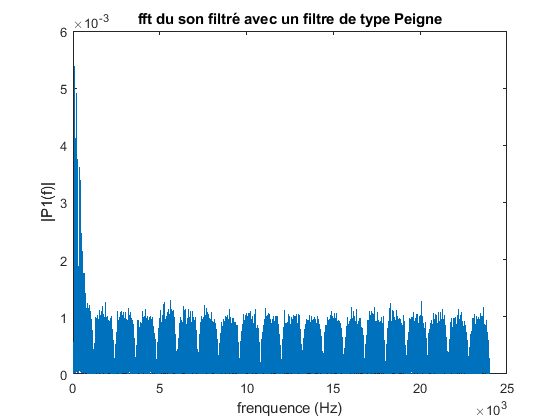



N     = 40 ;   % Order
BW    =  1000;% Bandwidth
Apass = 3;    % Bandwidth Attenuation

[b, a] = iircomb(N,...
    BW/(sampleRate/2),...
    Apass, 'peak');


combFilt    = dfilt.df2(b, a);

resComb = filter(combFilt,son_2_avec_perturbation);
figure
fftPlotter(resComb,sampleRate);
title('fft du son filtré avec un filtre de type Peigne')

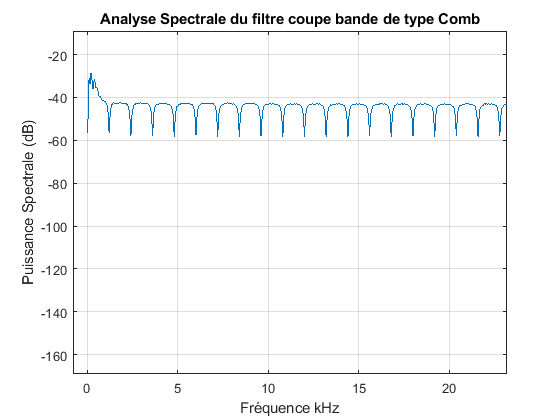


figure
SpectralAnalyser(resComb(:,1),sampleRate,frequencyLimits,0,[0 15]);
title(['Analyse Spectrale du filtre coupe bande de type Comb'])

%sound(resComb,sampleRate);
%audiowrite('Block\resComb.wav',resComb,sampleRate);


On peut voir que comme dans le cas du son 1, les filtres de type peignes ne sont pas appropriées pour filtrer un bruit gaussien. Comme pour le son 1, ces filtres (les filtres coup-bande) ne vont couper que certaines fréquences spécifiques, ce qui est peu utile dans ce cas si car les perturbations sont sur l'ensemble de la plage fréquencielle. 

Cependant, dans le cas d'un bruit 60 Hz dans le signal d'une antenne à cause d'un courant AC de la machinerie voisine, le filtre coupes-bande seraient très utiles. Rappelons ici que ce filtre n'est pas utilisé pour son appliquation spécique au projet, mais parce qu'il est implémenté de facon différente.

maintenant un filtre coupe-Bande de type qui est lui aussi réputé pour avoir une bande passnante stable sans ripple.

## Application d'un filtre Chebychev

 Pour le son 1, Le filtre passeband de chebychev fut un grand succes. Essayons encore, mais cette fois-ci en appliquant les fréquences de coupures approximatives de la voix humaine. 

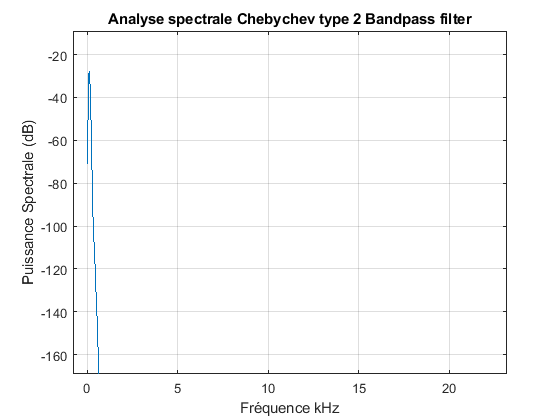

Fstop1 = 15;  % First Stopband Frequency
Fstop2 = 600;  % Second Stopband Frequency
Astop  = 130;   % Stopband Attenuation (dB)
filtOrder = 12; % Order

% Construct an FDESIGN object and call its CHEBY2 method.
h  = fdesign.bandpass('N,Fst1,Fst2,Ast', filtOrder, Fstop1, Fstop2, Astop, sampleRate);
cheby2 = design(h, 'cheby2');

resCheb = filter(cheby2,son_2_avec_perturbation);

figure
SpectralAnalyser(resCheb,sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale Chebychev type 2 Bandpass filter')

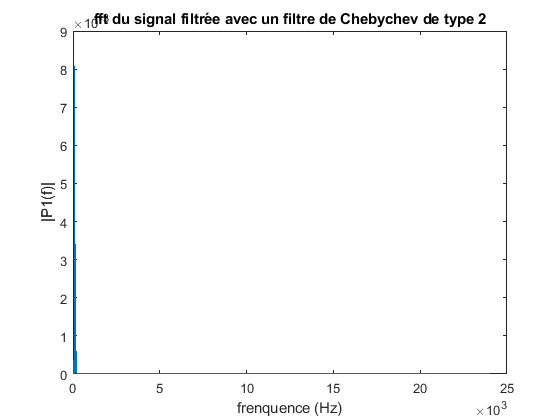

%xlim([0 20])
%ylim([-120 24])



figure
fftPlotter(resCheb,sampleRate)
title('fft du signal filtrée avec un filtre de Chebychev de type 2')


%sound(resCheb,sampleRate);
%audiowrite('Block\resCheb.wav',resCheb,sampleRate);

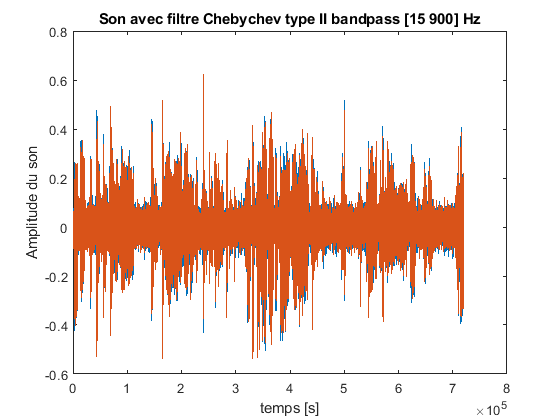

Fstop1 = 15;  % First Stopband Frequency
Fstop2 = 900;  % Second Stopband Frequency
Astop  = 130;   % Stopband Attenuation (dB)
filtOrder = 12; % Order

% Construct an FDESIGN object and call its CHEBY2 method.
h  = fdesign.bandpass('N,Fst1,Fst2,Ast', filtOrder, Fstop1, Fstop2, Astop, sampleRate);
cheby2 = design(h, 'cheby2');

resCheb2 = filter(cheby2,son_2_avec_perturbation);

figure
plot(sample_point,son_2_filtre_bandpass2)
title('Son avec filtre Chebychev type II bandpass [15 900] Hz')
xlabel('temps [s]')
ylabel('Amplitude du son')

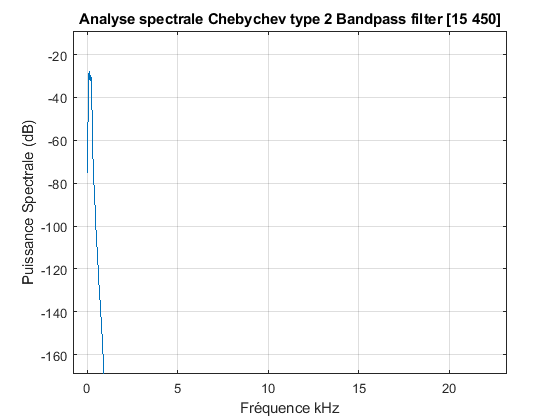



figure
SpectralAnalyser(resCheb2,sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale Chebychev type 2 Bandpass filter [15 450]')

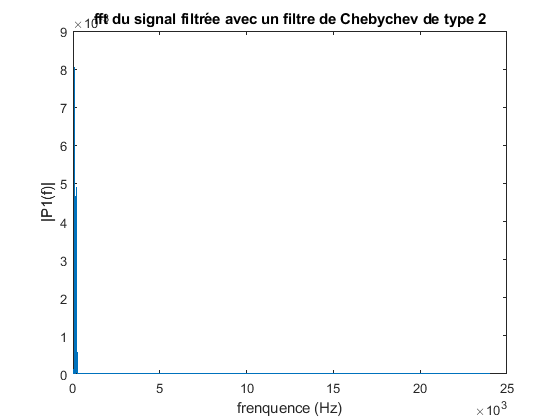

%xlim([0 20])
%ylim([-120 24])



figure
fftPlotter(resCheb2,sampleRate)
title('fft du signal filtrée avec un filtre de Chebychev de type 2')


%sound(resCheb2,sampleRate);
%audiowrite('Block\resCheb2.wav',resCheb2,sampleRate);

Le filtre à 600 Hz est le filtre qui retourne le moins de parasites, cependant il est aussi le filtre la voix semble étouffé à cause du manque de varité fréquencielle. Ce qui donne cet effet étouffé à la voix du narrateur.

À une fréquence de coupure de 900 Hz, les 300 Hz supplémentaires de font facilement entendre. Il faut noter qu'en contrepartie, le bruit est aussi plus présent.

Savons d'un pont de vue théorique que dans ce scénrio spécifique, le filttre de type chebychev de type 2 est une meilleur option pour ce type de problème à cause de sa pande passante applatit et sans ripple. 

Comparons ce filtre avec un avec un filtre qui est est reconnue pour avoir une la meilleure vitesse de transition. Rappelons que d'un point du vue théorique une vitesse de transition est inutile pour isoler une voix humaine car la voix humaine possède une gamme de fréquence qui n'est pas fix. Les plus grands avantages de filtres Eliiptiques sont doncs théoriquement inutils.

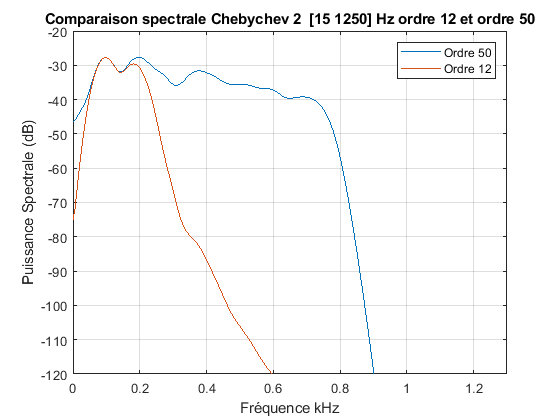

%Fstop1 = 15;  % First Stopband Frequency
%Fstop2 = 1250;  % Second Stopband Frequency
%Astop  = 130;   % Stopband Attenuation (dB)
filtOrder = 50; % Order

% Construct an FDESIGN object and call its CHEBY2 method.
h  = fdesign.bandpass('N,Fst1,Fst2,Ast', filtOrder, Fstop1, Fstop2, Astop, sampleRate);
cheby2 = design(h, 'cheby2');

resCheb3 = filter(cheby2,son_2_avec_perturbation);

figure
SpectralAnalyser(resCheb3,sampleRate,frequencyLimits,0,[0 15]);

hold on
SpectralAnalyser(resCheb2,sampleRate,frequencyLimits,0,[0 15]);
title('Comparaison spectrale Chebychev 2  [15 1250] Hz ordre 12 et ordre 50')
hold off
legend('Ordre 50','Ordre 12')
xlim([0 1.3])
ylim([-120 -20])

Il est possible voir la différence de performance entres le deux filtres en comparant les deux analyse spectrales du signal entre l'implémantation d'ordre 12 et 50. cette différence est aussi évidente lorsque l'on écoute les deux sons filtrées.

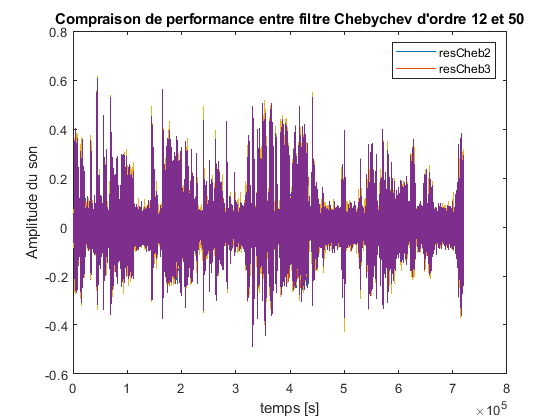

figure
plot(sample_point,resCheb2)
hold on;
plot(sample_point,resCheb3)
title('Compraison de performance entre filtre Chebychev d''ordre 12 et 50') 
xlabel('temps [s]')
ylabel('Amplitude du son')
legend('resCheb2','resCheb3')
hold off


%sound(resCheb3,sampleRate);
%audiowrite('Block\resCheb3.wav',resCheb3,sampleRate);


## Eliptic bandpass

Sachant que la vitesse de transition semble avoir une importance. Essayons,  un filtre qui est reconnue pour avoir une d'emblé la meilleur vitesse de transition.  

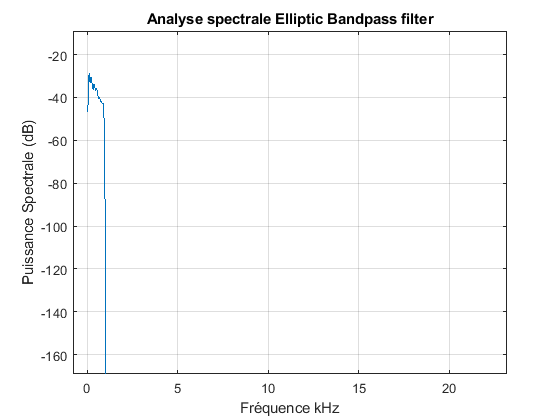



d = designfilt('bandpassiir','FilterOrder',filtOrder, ...
    'PassbandFrequency1',Fstop1,'PassbandFrequency2',Fstop2, ...
    'PassbandRipple',3, ...
    'StopbandAttenuation1',40,'StopbandAttenuation2',Astop, ...
    'SampleRate',sampleRate);

resEllip= filter(d,son_2_avec_perturbation);


figure
    SpectralAnalyser(resEllip,sampleRate,frequencyLimits,0,[0 15]);
    title('Analyse spectrale Elliptic Bandpass filter')

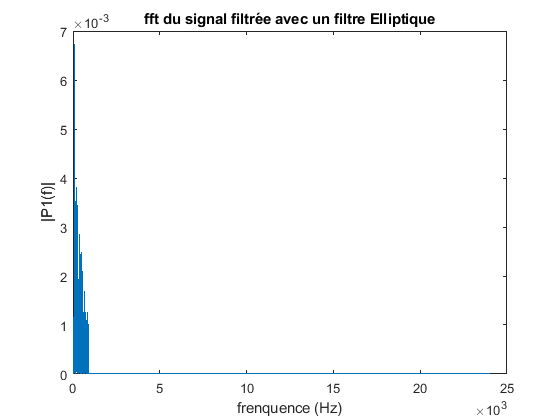



figure
    fftPlotter(resEllip,sampleRate);
    title('fft du signal filtrée avec un filtre Elliptique')

## comparaison Chebychev 2 and Elliptic bandpass filters

   Savons d'un pont de vue théorique que dans ce scénrio spécifique, le filttre de type chebychev de type 2 est une meilleur option pour ce type de problème à cause de sa pande passante applatit et sans ripple. 

Comparons ce filtre avec un avec un filtre qui est est reconnue pour avoir une la meilleure vitesse de transition. Rappelons que d'un point du vue théorique une vitesse de transition est inutile pour isoler une voix humaine car la voix humaine possède une gamme de fréquence qui n'est pas fix. Les plus grands avantages de filtres Eliiptiques sont doncs inutils.

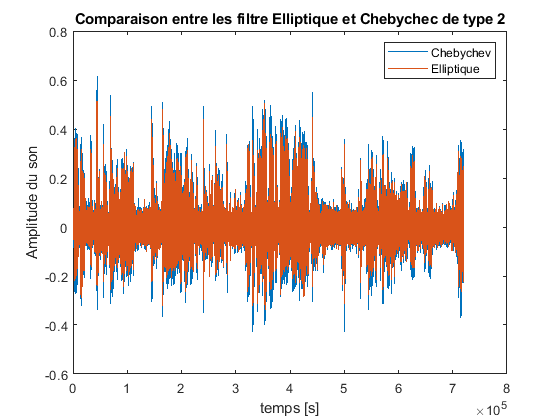

figure
    plot(sample_point,resCheb3(:,1));
    hold on;
    plot(sample_point,resEllip(:,1));
    title('Comparaison entre les filtre Elliptique et Chebychec de type 2')
    xlabel('temps [s]')
    ylabel('Amplitude du son')
    legend('Chebychev','Elliptique');
    hold off;


    
    
%sound(resEllip,sampleRate);
%audiowrite('Block\resEllip.wav',resEllip,sampleRate);

## Wavelet analysis

Comme 6iem filtre plusieurs solutions de filtres adaptatifs ont étés temptés. Les pricipaux ont été les types LMS (Least Mean Square) ainsi que certains algorthmes ont étés discarté, faute de temps. Cependant,  l'approche suivante qui est basé sur l'anayse par wavelets tel que définie [[https://www.hpl.hp.com/hpjournal/94dec/dec94a6a.pdf](https://www.hpl.hp.com/hpjournal/94dec/dec94a6a.pdf) ] a démontré des résultats interessants.

 Contrairement aux séries de Fourier qui font du dévloppement sous fomre de série trigonométriques, les wavelets procède au développement de fonctions sous forme de translations et de dilatations. Le résultat est exprimé sous forme temporel ainsi que fréquencielle. En pratique les wavelets sont utilisées pour traiter des signaux qui sont non stationnaires telque la voix. 

L'approche suivant, est une fonction integré de réduction du bruit par machine learning sur matlab qui utilise l'analyse par wavelets.

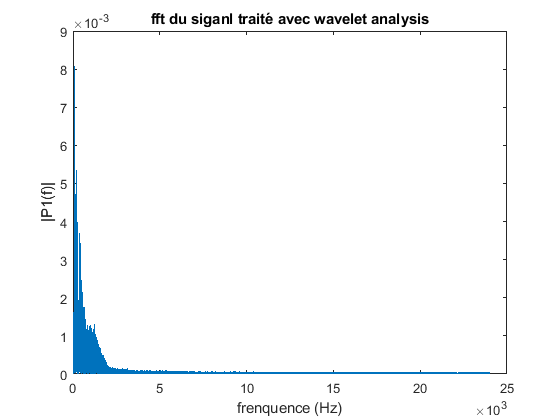

datsignal = son_2_avec_perturbation(:,1) ;



resDenoise = wdenoise(datsignal,4, ...
    'Wavelet', 'sym8', ...
    'DenoisingMethod', 'minimax',...
    'ThresholdRule', 'Hard', ...
    'NoiseEstimate', 'LevelDependent');

figure
    fftPlotter(resDenoise,sampleRate);
    title('fft du siganl traité avec wavelet analysis')


%sound(resDenoise,sampleRate);
%audiowrite('Block\resDenoise.wav',resDenoise,sampleRate);

Une grande partie du bruit gaussien a été filtré mais des parasites notables ont été introduits. 